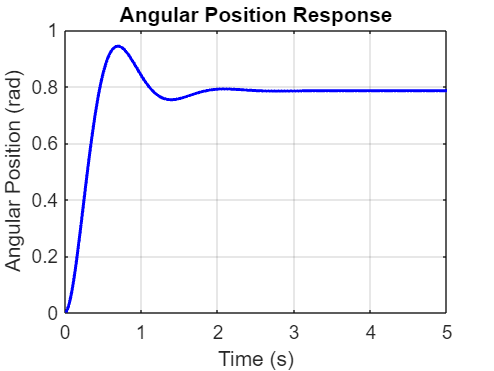

% Proportional Controller for a DC Motor

% Define motor parameters
R = 1;       % Armature resistance (ohms)
L = 0.5;     % Armature inductance (Henries)
K = 0.1;     % Motor constant (back EMF constant) (Volts-sec/rad)
J = 0.02;    % Moment of inertia of the rotor (kg*m^2)
b = 0.1;     % Damping coefficient (N*m*s/rad)
Ke = 0.1;    % Motor constant (Volts-sec/rad)
Kp = 5;     % Proportional gain

% Define setpoint
theta_setpoint = pi/4;  % Desired position (radians)

% Simulation parameters
timestep = 0.01;    % Time step (s)
total_time = 5;      % Total simulation time (s)
time = 0:timestep:total_time;

% Initialize variables
theta = zeros(size(time));  % Angular position
omega = zeros(size(time));  % Angular velocity
V = zeros(size(time));      % Applied voltage

% Simulate the system with proportional control
for i = 1:length(time)-1
    % Compute error (difference between setpoint and current position)
    error = theta_setpoint - theta(i);
    
    % Compute control action (proportional term only)
    control_action = Kp * error;
    
    % Compute back EMF
    EMF = Ke * omega(i);
    
    % Compute applied voltage (input to the motor)
    V(i) = control_action + EMF;
    
    % Compute torque
    torque = K * V(i);
    
    % Compute acceleration (from the equation of motion)
    alpha = (torque - b * omega(i)) / J;
    
    % Update velocity and position using Euler's method
    omega(i+1) = omega(i) + alpha * timestep;
    theta(i+1) = theta(i) + omega(i+1) * timestep;
end

% Plot results
figure;

plot(time, theta, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Angular Position (rad)');
title('Angular Position Response');
grid on;

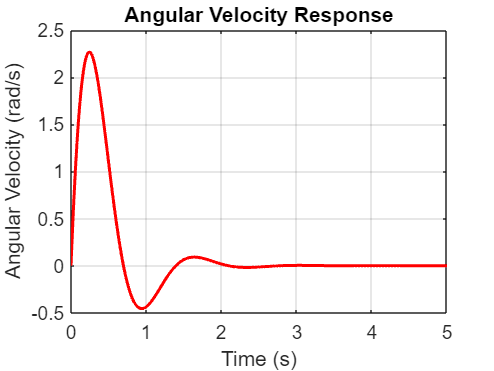



plot(time, omega, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
title('Angular Velocity Response');
grid on;

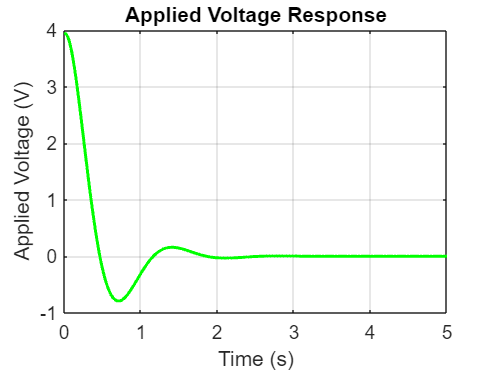



plot(time, V, 'g', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Applied Voltage (V)');
title('Applied Voltage Response');
grid on;